# Pozrikidis Channel Geometry with Bernardi Boundary Pressure (Stokeslets Only)

## Boundary Velocity

The velocity at the top and bottom boundary are given by:


$$v(x,2H) = v(x, 0) = \left\{ \begin{array}{lr} 0, & x\in[0,c]\cup [L+c,L+2c]\\ \pm {\rm Da}\, p_T(x) & x\in(c,L+c) \end{array} \right.$$


Following Bernardi on the domain $[0,L+2c]\times[0,2H]$: 


$$p_T(x, 2H) = p_T(x,0) = \left\{ \begin{array}{lr} Gc-Gx +  \frac{G}{\lambda}\tanh(\lambda L/2), & x\in (0,c)\\ -\frac{G}{\lambda\cosh(\lambda L/2)}\sinh(\lambda (x-x_m)) & x\in(c,L+c) \\ Gc+GL-Gx- \frac{G}{\lambda}\tanh(\lambda L/2), & x\in (L+c,L+2c)\end{array} \right.$$


where $x_m=(L+2c)/2$ is the midpoint of the domain and $\lambda$ satisfies $0=({\rm Da}-H/2)\lambda\cot(\lambda H)\cos(\lambda H) + \frac12\cos(\lambda H)-\frac{\lambda H}{2}\sin(\lambda H)$. (Note: For ${\rm Da}=0.3, H=1$, we have $\lambda\approx 0.74$.)

In the non-permeable region, we have $v=0$ and $u=0$. At the inlet, we have fully developed Poiseuille flow ($u=u_{pois}$, $v=0$). At the outlet, the Poiseuille flow is scaled by a factor $\chi$ to give $u=\chi u_{pois}$ and $v=0$.

The velocity boundary conditions in this instance are


$$v(x,2H) = v(x, 0) = \left\{ \begin{array}{lr} 0, & x\in[0,c]\cup [L+c,L+2c]\\ \mp\frac{{\rm Da} \, G}{\lambda\cosh(\lambda L/2)}\sinh(\lambda (x-x_m)) & x\in(c,L+c) \end{array} \right.$$



$$u(x,2H) = u(x, 0) = 0\quad\text{for}\quad x\in[0,L+2c]$$


clear
close all 

addpath('./stokeslets_codes'); 

method_for_plots = 'Stokeslets Only (channel with permeable section)';

#### **Set parameters**

- Blob choice 2 uses $\psi$ from 2021 paper

- Blob choice 1 uses $\phi$ from 2021 paper

%set Darcy number
Da = 0.4;
%viscosity
mu = 1; 
%choose blob
blob_num = 2;
% scale factor for epsilon*ds_y
ep_factor = 0.5;

% Poiseuille flow strength
G = 4;
% chi in PC paper: "dimensionless coeff. determining exit flow rate"
chi = 1;

% Number of source and target points
N = 160; % Number of source points (along top  and bottom boundaries)
Nx2 = 40; % Number of target points in y direction for full channel calc
Nx1 = floor(pi*Nx2); % Number of target points in x direction for full channel calc

#### **Define geometry and regularization**

% Setting forces and computing velocity
% Channel geometry
L = 3; % length of permeable portion of the channel
H = 1; % radius of the channel
c = 2*H; % extension length of the channel
xmin = 0;
xmax = L + 2*c;
xmid = (L+2*c)/2;
ymin = 0;
ymax = 2*H;

% Discretization step
ds_x = (xmax - xmin)/N;
ds_y = (ymax - ymin)/( ceil((ymax - ymin)/ds_x));

% Define blob size based on wall discretization 
ep = ds_y*ep_factor;

% Necessary for FB solution
% Use Newton's method to compute lambda
lambda = sqrt(2*Da);
fun = @(L) (Da-H/2)*L*cot(L*H)*cos(L*H) + cos(L*H)/2 - H*L*sin(L*H)/2;
lambda = fzero(fun, lambda);
% define the functions g(y) and g'(y) from the notes
g=@(y) (Da - H/2)*cot(lam*H)*sin(lam*y) + y/2.*cos(lam*y);
gp=@(y) (Da - H/2)*lam*cot(lam*H)*cos(lam*y) + 1/2.*cos(lam*y) - lam*y/2.*sin(lam*y);

% Check fluxes
influx = G*H^3*2/3; % flux into channel
topflux = Da*G*(cosh(lambda*L/2)-1)/lambda^2/cosh(lambda*L/2);
disp(['Inlet flux = ',num2str(influx)])

Inlet flux = 2.6667


disp(['Top flux in half-channel = ',num2str( topflux)])

Top flux in half-channel = 1.1107


disp(['Bottom flux in half-channel = ',num2str( topflux)])

Bottom flux in half-channel = 1.1107


disp(['Therefore, the flux out of the channel at the midcross-section is ',num2str(influx-2*topflux)])

Therefore, the flux out of the channel at the midcross-section is 0.44534


#### **Discretization**

tb = top/bottom

lr = left/right

source point coordinates organized stacked:

    [top; bottom; left; right]

%discretization step of top/bottom walls
stb = xmin+ds_x/2:ds_x:xmax-ds_x/2;
stb = stb';
%discretization step of left/right wall (inlet/outlet)
slr = ymin+ds_y/2:ds_y:ymax-ds_y/2;
slr = slr';

% Define coordinates on each wall (x-coord,y-coord) (source points)
y1_top = stb;   y2_top = ymax*ones(size(stb)); % top wall coordinates (y1_top,y2_top)
y1_bot = stb;   y2_bot = ymin*ones(size(stb)); % bottom wall coordinates (y1_bot,y2_bot)
y1_left = xmin*ones(size(slr));   y2_left = slr; % left wall coordinates (y1_left,y2_left)
y1_right = xmax*ones(size(slr));   y2_right = slr; % right wall coordinates (y1_right,y2_right)
y1 = [y1_top; y1_bot; y1_left; y1_right]; %x-coordinates of all boundary points
y2 = [y2_top; y2_bot; y2_left; y2_right]; %y-coordinates of all boundary points

% Points where velocity will be computed within the channel (target points)
xx1 = linspace(xmin,xmax,Nx1);
xx2 = linspace(ymin,ymax,Nx2);
[x1m, x2m] = ndgrid(xx1, xx2);
x1 = x1m(:); %x-coords of points where computing velocity
x2 = x2m(:); %y-coords of points where computing velocity


#### **Set boundary velocities**

% Define quadrature weights cooresponding to wall coordinates.
% Currently using midpoint rule.
% Weights for targets/sources at corners and just outside inlet/outlet are
% set to ds_y (possibly not correct) but will be divided out so shouldn't cause issues.
wt = [ds_x*ones(size(y1_top)); ds_x*ones(size(y1_bot)); ds_y*ones(size(y1_left)); ds_y*ones(size(y1_right))];

% No slip at top and bottom 
% (set to 0, although technically unknown in permeable region)
u1_top_exact = zeros(size(y1_top));
u2_top_exact = zeros(size(y2_top));
u1_bot_exact = zeros(size(y1_bot));
u2_bot_exact = zeros(size(y2_bot));
% Poiseuille flow at inlet and outlet
u_pois = -G*(y2_left - ymin).*(y2_left - ymax)/2;%/2/mu;
u1_left_exact = u_pois;
u1_right_exact = chi*u_pois;
u2_left_exact = zeros(size(slr));
u2_right_exact = zeros(size(slr));

% Analytical (approx.) velocity in permeable region
idx_perm = find(c < y1_top & y1_top < L+c);
u2_top_exact(idx_perm) = -Da*G*sinh(lambda*(y1_top(idx_perm)-xmid))/(lambda*cosh(lambda*L/2));
u2_bot_exact(idx_perm) = Da*G*sinh(lambda*(y1_top(idx_perm)-xmid))/(lambda*cosh(lambda*L/2));

% Set zero velocity contribution from stokeslets on permeable parts
u1_bd_exact = [u1_top_exact; u1_bot_exact; u1_left_exact; u1_right_exact];
u2_bd_exact = [u2_top_exact; u2_bot_exact; u2_left_exact; u2_right_exact];

#### **Find forces on boundary due to known velocities**

% All four sides of channel
f_temp = RegStokeslets2D_velocitytoforce_KK([y1,y2], [y1,y2], [u1_bd_exact,u2_bd_exact], ep, mu, blob_num,wt);

log10 of condition number of Mat: 2.7357
condition number of Mat+D: 921.8399
size of Mat+D: 824  824


#### **Compute velocity and pressure everywhere due to boundary forces**

% % Compute velcoity using Bernardi BCs % % 
ug = RegStokeslets2D_forcetovelocity([y1,y2],f_temp,[x1,x2],ep,mu,blob_num,wt);
ug1 = ug(:,1);
ug2 = ug(:,2);
u1m = reshape(ug1,size(xx1,2),size(xx2,2)); % x-coords of computed velocities everywhere
u2m = reshape(ug2,size(xx1,2),size(xx2,2)); % y-coords of computed velocities everywhere
ummag = sqrt(u1m.^2 + u2m.^2);

% compute pressure using Bernardi
p = RegStokeslets2D_forcetopressure([y1, y2], f_temp, [x1, x2], ep, mu, blob_num, wt);
pm = reshape(p,size(xx1,2),size(xx2,2));

### Plotting

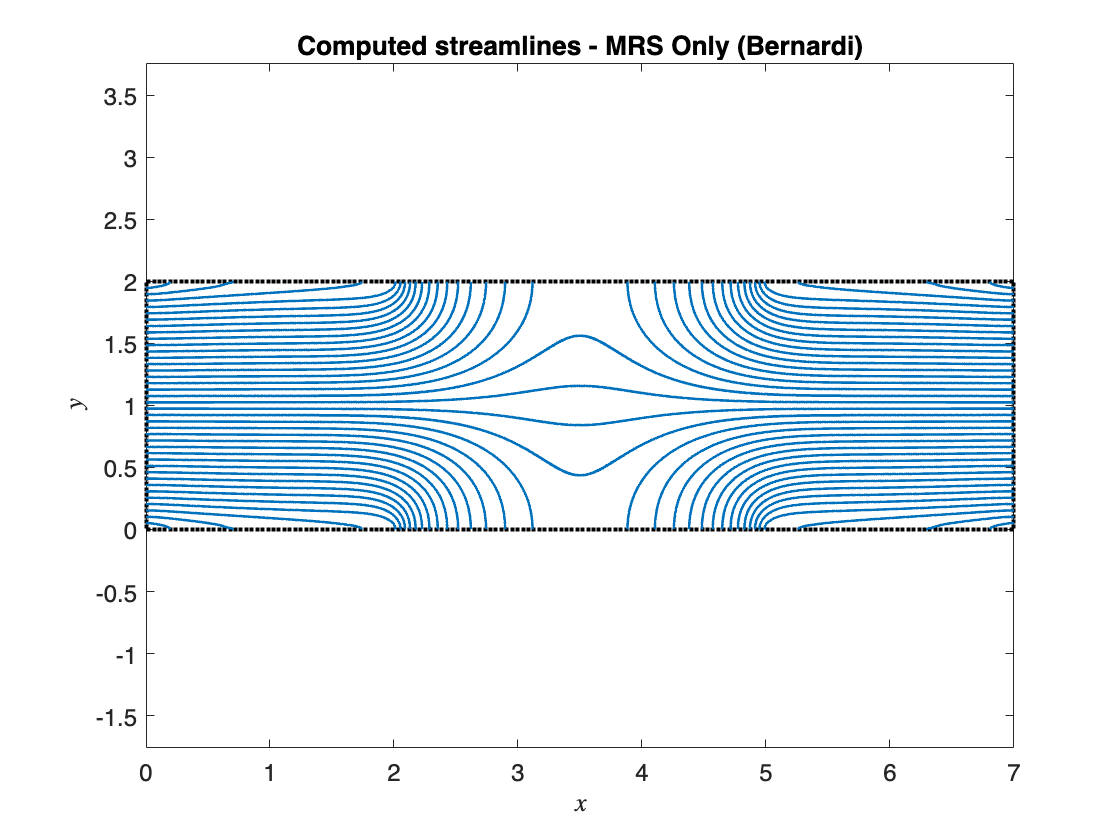

[x1gg, x2gg] = meshgrid(xx1, xx2);

figure
plot(y1, y2, 'k.')
hold on

% Computed streamlines
hh1_comp = streamline(x1gg, x2gg, u1m', u2m', x1gg(1:end, 1), x2gg(1:end, 1)); % streamlines starting at left wall
hh2_comp = streamline(x1gg, x2gg, -u1m', -u2m', x1gg(1:end, end), x2gg(1:end, end)); % streamlines starting at right wall

strmLW = 1.3;
RGB = orderedcolors("gem");
set(hh1_comp, 'Color', RGB(1,:), 'linewidth', strmLW);
set(hh2_comp, 'Color', RGB(1,:), 'linewidth', strmLW);

title('Computed streamlines - MRS Only (Bernardi)')
xlabel('$x$', 'Interpreter', 'latex')
ylabel('$y$', 'Interpreter', 'latex')
axis equal
set(gca,'FontSize',12)

#### Quiver plot of exact velocities on boundaries for Bernardi

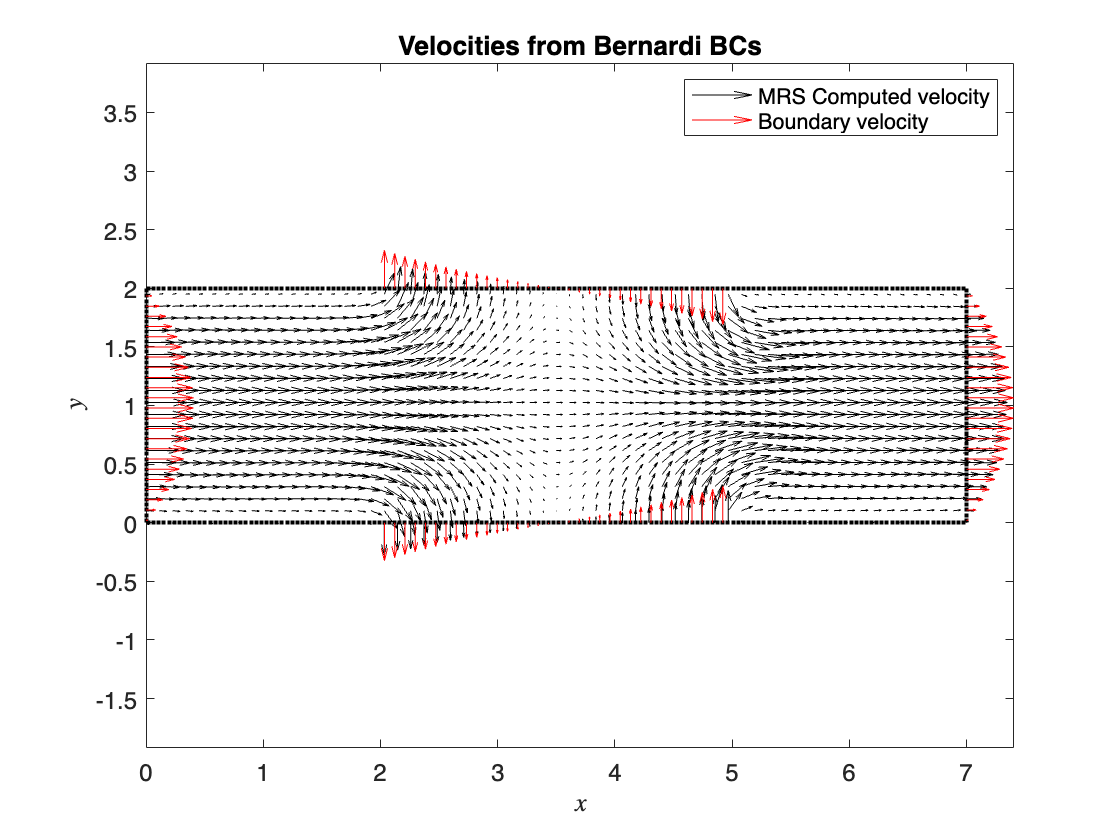

figure

skip = 2;

plot(y1,y2,'k.')
hold on
quiver(x1m(1:skip:end,1:skip:end),x2m(1:skip:end,1:skip:end),u1m(1:skip:end,1:skip:end),u2m(1:skip:end,1:skip:end), 1,'k','AutoScale','off')
quiver(y1(1:skip:end),y2(1:skip:end),u1_bd_exact(1:skip:end),u2_bd_exact(1:skip:end), 0.8,'r','AutoScale','off')

title('Velocities from Bernardi BCs')
legend('','MRS Computed velocity','Boundary velocity')
xlabel('$x$', 'Interpreter', 'latex')
ylabel('$y$', 'Interpreter', 'latex')
axis equal
set(gca,'FontSize',12)

#### pcolor plot of velocities everywhere with quiver of computed forces on boundaries for Bernardi

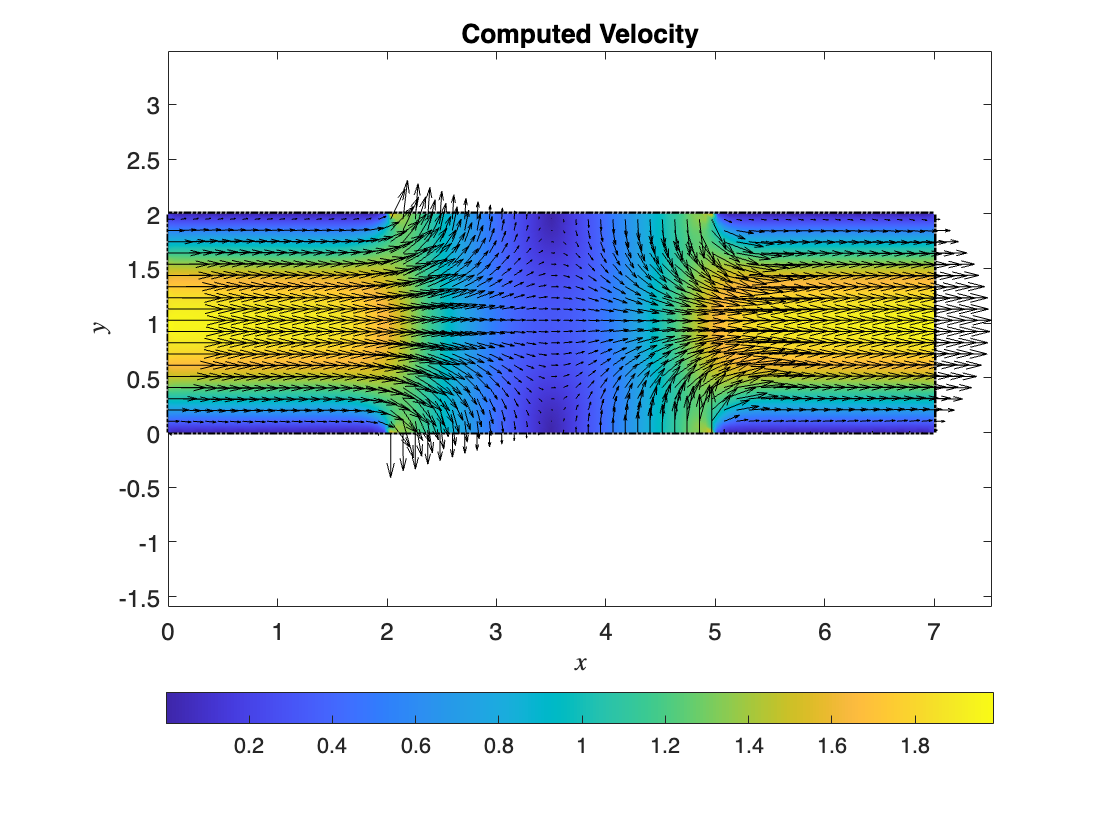

skip = 2;
scalefactor = 1.5;

figure
plot(y1,y2,'k.')
hold on
pcolor(x1m,x2m,ummag)
shading interp
colorbar('southoutside')
set(gca,'FontSize',12)

axis equal
quiver(x1m(1:skip:end,1:skip:end),x2m(1:skip:end,1:skip:end),u1m(1:skip:end,1:skip:end),u2m(1:skip:end,1:skip:end),scalefactor,'k','AutoScale','off')
title('Computed Velocity')
xlabel('$x$', 'Interpreter', 'latex')
ylabel('$y$', 'Interpreter', 'latex')
set(gca,'FontSize',12)

## Compute fluxes on of top and at inlet

% Flux across half the top boundary
idx_flux = find(y1_top < 0);
y1_flux = y1_top(idx_flux);

normals_top=zeros(length(y1_flux),2);
normals_top(:,2)=1;

Rtop = ds_x*sum(dot(normals_top, [zeros(size(y1_flux)), u2_top_exact(1:length(y1_flux))]))

Rtop = 0

topflux = Da*(G)*(cosh(lambda*L)-1)/lambda^2/cosh(lambda*L);
disp(['Inlet flux = ',num2str(influx)])

Inlet flux = 2.6667


disp(['Top flux in half-channel = ',num2str( topflux)])

Top flux in half-channel = 2.0198


disp(['Bottom flux in half-channel = ',num2str( topflux)])

Bottom flux in half-channel = 2.0198


disp(['Therefore, the flux out of the channel at the midcross-section is ',num2str(influx-2*topflux)])

Therefore, the flux out of the channel at the midcross-section is -1.3729





% Flux across inlet
normals_side = -ones(length(y2_left),2);
normals_side(:,2) = 0;

inlet_flux = ds_y*sum(dot(normals_side, [u1_left_exact, zeros(size(y2_left))]))

inlet_flux = -2.6673